# Lab3: Contrast, equalization and quantization.

## Contrast changes in an image

Contrast can be defined as the *relative difference in intensity between a point of an image and its neighborhood*. The human visual system is more sensitive to contrast than absolute luminance value and, therefore, we are able to perceive the world around us similarly despite the large illumination changes taking place throughout the day.

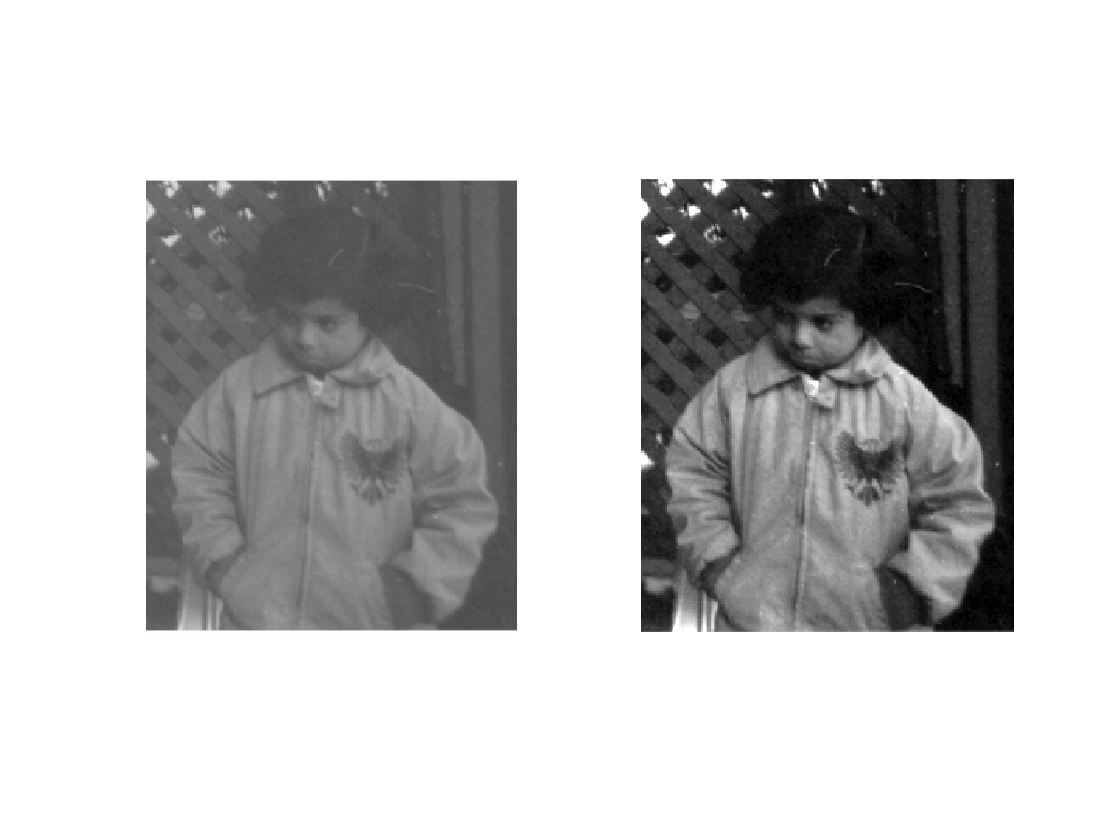

figure;
subplot(1,2,1); imshow(imread('low_contrast.png'));
subplot(1,2,2); imshow(imread('high_contrast.png'));

The aim of this first part of the practice is to experiment with different functions for changing the  contrast and to see their effects on the perception of the image.

The contrast changes with which we are going to work are applied at the pixel level; this means that the modification of the value of a particular pixel depends only on its original value (thus not involving, for example, the values of neighboring pixels).

## Linear contrast changes

In Matlab you can use the *imadjust* function to perform linear contrast changes. Specifically, the function call with the following parameters:

% I_cont = imadjust(I,[low_in;high_in],[low_out;high_out]);
help imadjust

 imadjust Adjust image intensity values or colormap.
    J = imadjust(I) maps the values in intensity image I to new values in J
    such that 1% of data is saturated at low and high intensities of I.
    This increases the contrast of the output image J.
 
    J = imadjust(I,[LOW_IN; HIGH_IN],[LOW_OUT; HIGH_OUT]) maps the values
    in intensity image I to new values in J such that values between LOW_IN
    and HIGH_IN map to values between LOW_OUT and HIGH_OUT. Values below
    LOW_IN and above HIGH_IN are clipped; that is, values below LOW_IN map
    to LOW_OUT, and those above HIGH_IN map to HIGH_OUT. You can use an
    empty matrix ([]) for [LOW_IN; HIGH_IN] or for [LOW_OUT; HIGH_OUT] to
    specify the default of [0 1]. If you omit the argument, [LOW_OUT;
    HIGH_OUT] defaults to [0 1].
 
    J = imadjust(I,[LOW_IN; HIGH_IN],[LOW_OUT; HIGH_OUT],GAMMA) maps the
    values of I to new values in J as described in t

This functions changes the input pixel value to the output desired value in the following way:

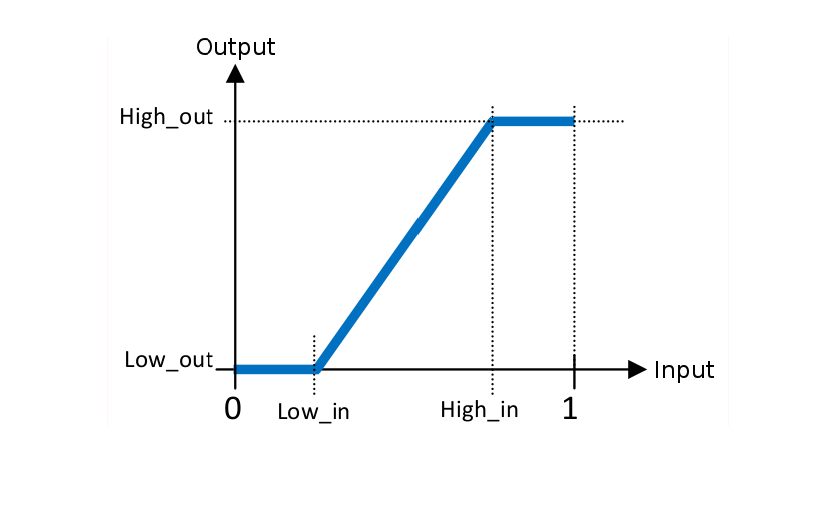

% Note that this snippet of code is just to show the linear contrast changes mapping
figure; imshow(imread('linear_change.png'));

If you are working with doubles, many different operations can be applied by setting the ranges of inside the *imadjust *function, for instance, we can narrow the histogram of the input image within 0.4 and 0.6:

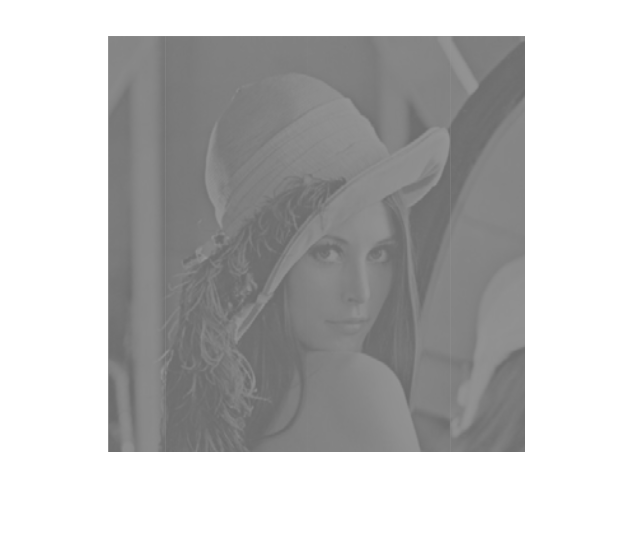

I = imread('lena.png');
I_cont = imadjust(I,[0;1],[0.4;0.6]);
figure; imshow(I_cont);

## Nonlinear contrast changes

The function *imadjust* allows you to add a final argument, *gamma*, to perform nonlinear contrast changes like ones shown in the figure:

% Note that this snippet of code is just to show the non linear contrast changes mapping
figure; imshow(imread('nonlinear_contrast_change.png'));

You can add this gamma value simply by: 

% I_cont = imadjust(I,[low_in;high_in],[low_out;high_out],gamma);

## Image histogram equalization

The histogram of an image represents the relative frequency of gray levels in the image. Techniques for modifying the histogram of an image are useful for increasing the contrast of an image with highly concentrated histogram.

To calculate the histogram of an image you can use function *imhist*.

To equalize an image you can follow the procedure on the page 105 of the notes. This notes are also attached in the Supplementary Notes inside the lab pdf, as it was messy to include it here. 

## Entropy of an image

A statistical measure related to the histogram is the entropy of an image: H, in bits/pixel. The entropy can be approximated using the image histogram, $h\left(r_k \right)$, as follows (being $h\left(r_k \right)$ the gray levels are discrete or integer):


$$H = -\sum_{k=0}^{L-1}p_r(r_k)log_2(p_r(r_k)) ~bits / pixel$$


, with:


$$p_r(r_k) \cong \frac{h(r_k)}{\sum_{k=0}^{L-1} h(r_k)} ~k=0,...,L-1$$


## Quantization

**N-levels uniform quantizer**

In this section we will construct a uniform quantizer. The immediate way to quantize an image is to truncate the real values in the matrix to integers. You can use the function *round*, which rounds the real values of a matrix to their nearest integers.

When we use *round* for quantization, we can easily specify how many discrete gray levels we want to keep in the quantized image. Simply multiply the image by a certain value before applying *round*. For example:

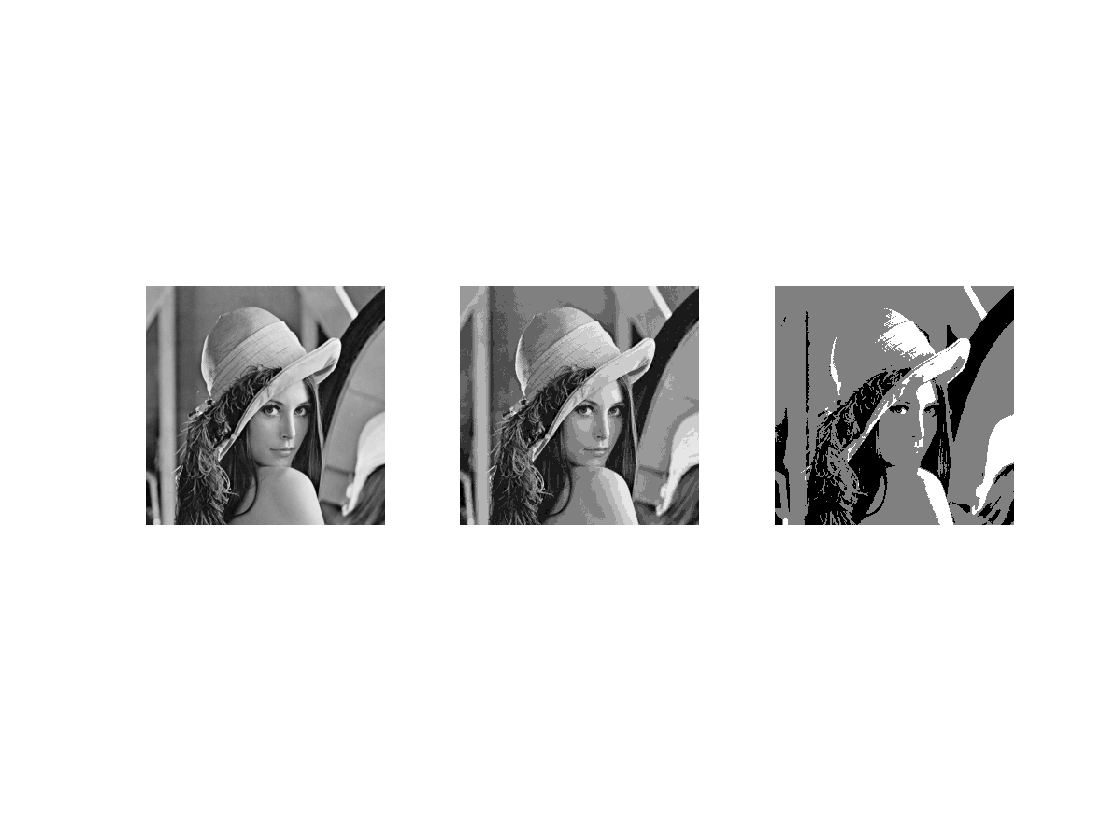

im = (imread('lena.png'));
min_value = min(min(im));
max_value = max(max(im));
    
M = double(max_value - min_value);

% Quantize with 58 levels
g1=57/M;  
g2=255/57;
quantized1 = round( g1 * ( im - min_value ) ) * g2 ;

% Quantize with 11 levels
g1=10/M;  g2=255/10;
quantized2 = round( g1 * ( im - min_value ) ) * g2 ;

% Quantize with 3 levels
g1=2/M;   
g2=255/2;
quantized3 = round( g1 * ( im - min_value ) ) * g2 ;

figure; 
subplot(1,3,1); imshow(quantized1);
subplot(1,3,2); imshow(quantized2);
subplot(1,3,3); imshow(quantized3);

From the previous experiment, we included the function *uniform_quantizer* in the lab zip file. Now you can use it to experiment with different quantization levels (different values of N).

## Quantitative criteria of fidelity

The criteria of fidelity of an image is useful for measuring the quality of a certain image. Recall (see notes, page 83) that the problem can be stated mathematically as follows: given a certain image $I$, and another image $\hat{I}$, obtained from $I$ by encoding, transmission, restoration etc., we have a measure of distortion that tells us what is the quality of $\hat{I}$ with respect to $I$. There are two types of criteria to evaluate the quality of an image: subjective and objective (quantitative). One of the most widely used quantitative measures is the mean squared error. Suppose we have a statistical distribution of a group of images, and that $I$ and $\hat{I}$ are images of this group. In this case, the mean squared error is:


$$e[i,j] = \widehat{I}[i,j] - I[i,j]$$



$$\sigma_{ms}\equiv E\left \{ \left| e[i,j] \right |^2 \right \} $$


where E represents the expectation. When we do not have the statistics of the images, we use the mean squared error defined by


$$\sigma_{ls} \equiv \frac{1}{NM} \sum_{i=1}^{N} \sum_{j=1}^{M} \left| e[i,j] \right|^2$$


(we assume that the images have been digitized and are represented by M-by-N matrixes). There is a function, **immse**, which calculates the mean squared error. In many applications, the mean squared error is expressed as a signal to noise ratio, measured in decibels (dB), SNR is defined by the expression:


$$SNR = 10log_{10} \frac{\sigma^2}{\sigma_e^2}$$



$$PSNR = 10log_{10} \frac{d^2}{\sigma_e^2}$$


where $$\sigma^2$$ is the variance of the original image and $$\sigma_e^2$$ might be $ $\sigma_{ms}$$ or $$\sigma_{ls}$$. Another definition is widely used PSNR (above), where d is the difference of the extreme values of the image (usually 255). We also have the PSNR built-in function **psnr**.